## Segmentació per K-means

**Objectiu**: implementar un sistema assistit per segmentar objectes en imatges en color. (imatges amb un objecte diferenciat del fons pels colors)

Procediment: 

L'Usuari indicarà manualment l'objecte a segmentar amb un marc rectangular.

Resposta: l'objecte segmentat indicant el seu perfil en vermell.

I = imread("tiger3.jpg");
imshow(I);

% comprovar que estigui en RGB
[~, ~, chans] = size(I);   % chans: canals RGB
chans

chans = 3

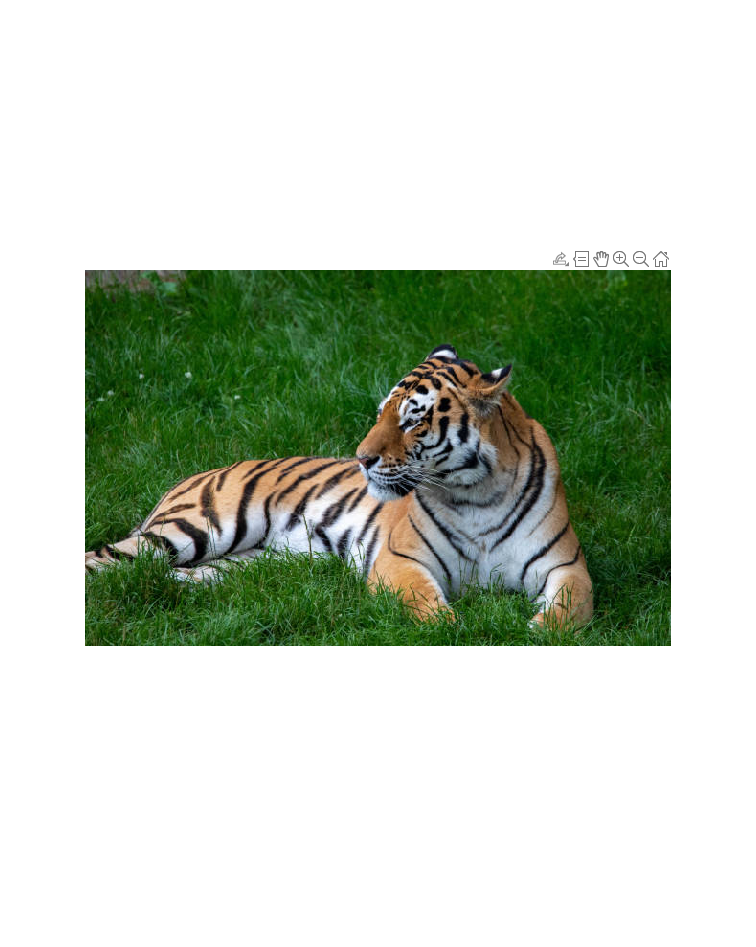


% obtenir rectangle
rect = getrect;

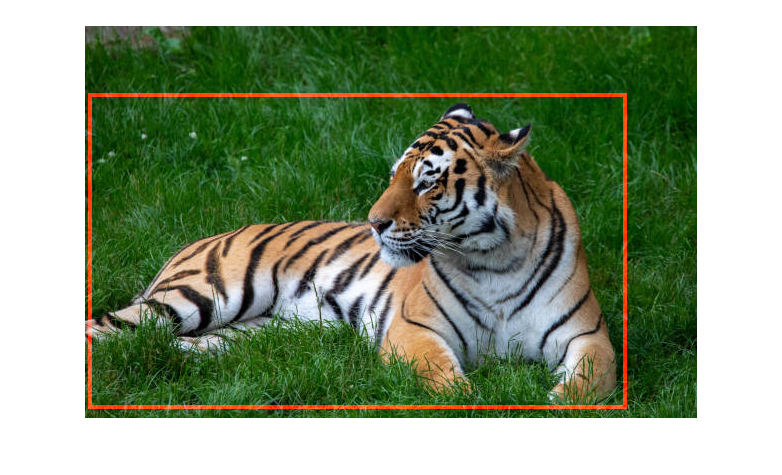

Iretallada = imcrop(I,rect);

I2 = I;  % imatge auxiliar on marcar el rectangle vermell
x = uint32(rect(1)); y = uint32(rect(2));
w = uint32(rect(3)); h = uint32(rect(4));

b = 3;  % mida bora del rectangle vermell

% Dibuixar rectangle vermell a l'imatge original
I2(y:y+b, x:x+w, 1) = 255;   % 1r les files i despres columnes i despres la component vermella
I2(y:y+h, x:x+b, 1) = 255;
I2(y+h-b:y+h, x:x+w, 1) = 255;
I2(y:y+h, x+w-b:x+w, 1) = 255;

imshow(I2);

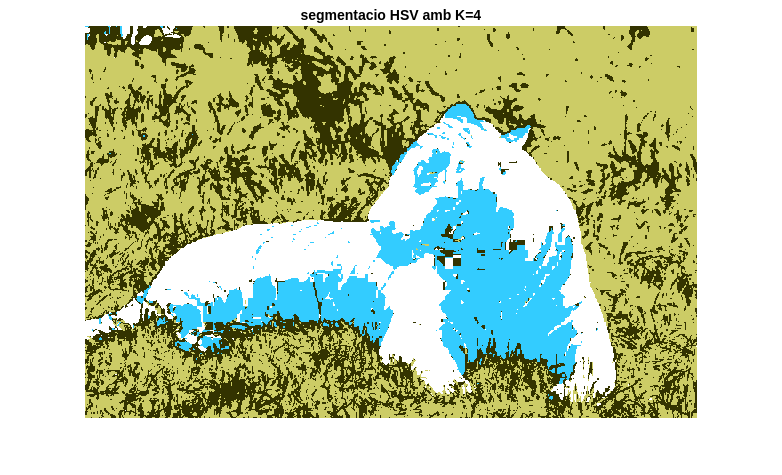

% passar a HSV   (vigilar aritmetica ciclica dels angles, el 0 i 360 son el mateix, s'ha de vigilar ja que treballem amb distancies)

hsv = rgb2hsv(I);    

H = hsv(:,:,1);  S = hsv(:,:,2);  V = hsv(:,:,3);

Hx = sin(H*(2*pi));   % apliquem el sinus ja que es una funcio que es repeteix cada 360º
Hy = cos(H*(2*pi));   % internament en radians, per aixo passem de graus a rad multiplicant per 2*pi  (hue va de 0 a 1)

% vector de caracteristiques
O = [Hx(:), Hy(:), S(:), V(:)];    % Una millor implementacio seria sense V, ja que es la component de la iluminacio i pot jugar una mala pasada

% reduir nombre colors, K-mean
k = 4;

% obtenir la classificacio C, agrupant els colors en k classes
C = kmeans(O, k, 'Distance', 'sqeuclidean'); % tipus distancies: sqeuclidean cityblock hamming
eti = reshape(C, size(H));

valk = int2str(k);
titol = sprintf('segmentacio HSV amb K=%s', valk);

figure, imshow(eti,[]), title(titol);    % tenim regions sorolloses
colormap colorcube   % color fals, sino sortiria tot blanc

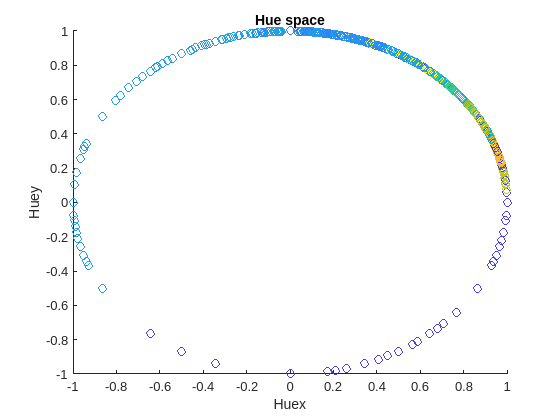

% mostrar la aritmetica ciclica, hauria de sortir un patro circular centrat en el (0,0)

figure, scatter(O(:,1),O(:,2),[],C);  % cada punt te el color especificat per la classificacio de C
xlabel('Huex'), ylabel('Huey');
title('Hue space')

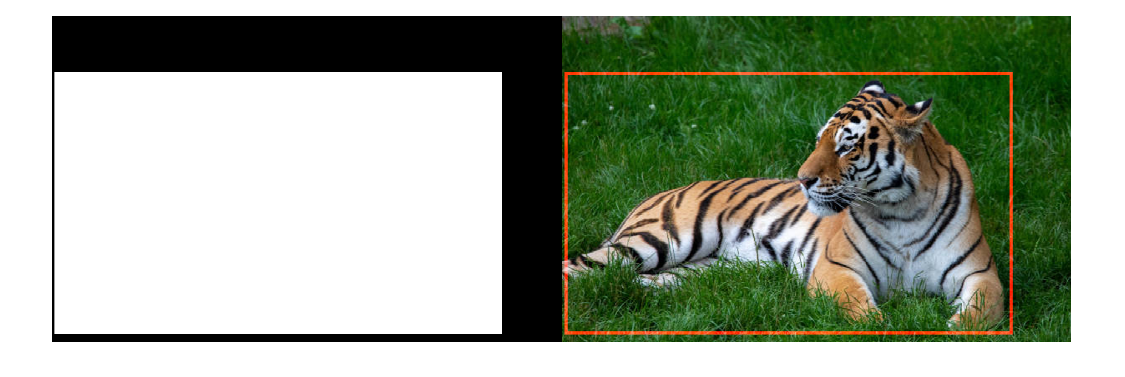

% Decidir quins colors de C formen part de l'objecte. Contar quins colors cauen majoritariament dins la finestra. 

% mascara binaria
MASK = false(size(I,1), size(I,2));    % inicialment tot a 0 i sera tambe la regio fora del rectangle
MASK(y:y+h-1, x:x+w-1) = true;   % posar a 1 dins el rectangle    (-1 perque els index comencen a 1)

montage({MASK,I2});

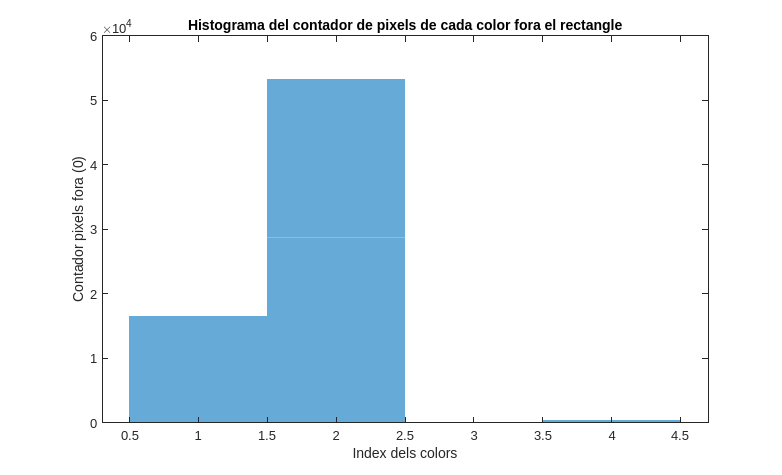

% Construir vector H que indica si un color cau dins el rectangel H = [C,MASK(:)]. H es una taula que indica si el color es dins o fora la mascara

 % tenim C on hi ha cada pixel el index del color que te
 % ara volem C2 on conte nomes 
H = [C, MASK(:)];   % conte dues columnes, la primera indica el index del color i la segona bool amb 1 si esta dins el rectangle

% Contar per cada color de C quants pixels han caigut fora i quans dins: Hist0 i Hist1. (la seva mida igual al nombre de classes k).
Hist0 = zeros(1,k);  % contador pixels fora
Hist1 = zeros(1,k);  % contador pixels dins

tots_colors = H(:,1);  % tenir un array amb cada pixel el seu index de color

colors_unics = unique(tots_colors);   % crear array amb els index dels colors unics, te mida k i contindra valors de 0 a k (tambe es podria calcular amb un bucle)

% contar nombre de 0s de H
 % per cada color
for color = 1:k
    grup_color_concret = tots_colors == color; % seleccionar nomes els mateixos colors a la iteracio concreta

    cont = sum( H(grup_color_concret, 2) == 0 );   % nomes sumar els pixels del grup de colors que estan a 0

    Hist0(color) = cont;  
end

% contar nombre de 1s de H
 % per cada color
for color = 1:k
    grup_color_concret = tots_colors == color; % seleccionar nomes els mateixos colors a la iteracio concreta

    cont = sum( H(grup_color_concret, 2) == 1 );   % nomes sumar els pixels del grup de colors que estan a 0

    Hist1(color) = cont;  
end


% graficar valors histogrames

% m'agradaria pintar cada barra de un color diferent aleatoriament, pero no me n'he ensortit
histogram('BinCounts', Hist0, 'BinEdges', 0.5:k+0.5, 'DisplayStyle', 'bar', 'EdgeColor', 'none');

xlabel('Index dels colors');
ylabel('Contador pixels fora (0)');
title('Histograma del contador de pixels de cada color fora el rectangle');

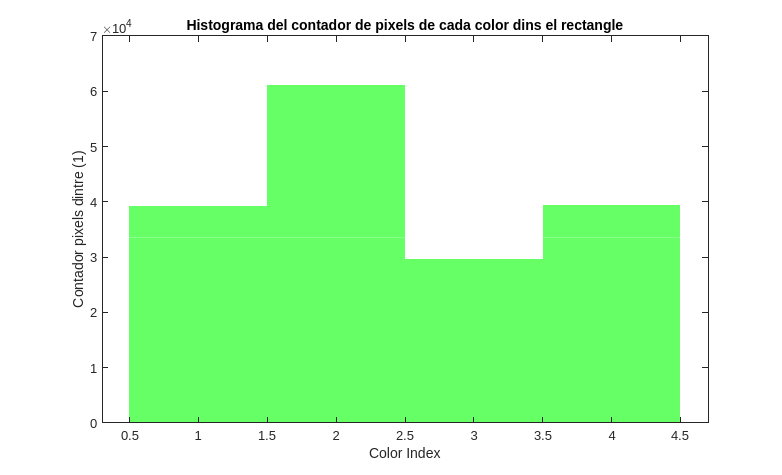


histogram('BinCounts', Hist1, 'BinEdges', 0.5:k+0.5, 'DisplayStyle', 'bar', 'EdgeColor', 'none', 'FaceColor', 'g');

xlabel('Color Index');
ylabel('Contador pixels dintre (1)');
title('Histograma del contador de pixels de cada color dins el rectangle');

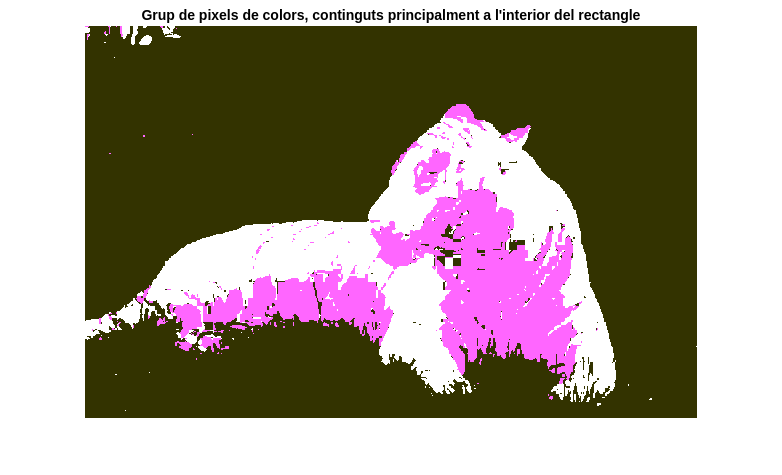

% Decidir si un representant de color pertany a la figura que es vol segmentar comparant les seves aparicions dins i fora del rectangle. 
% Guardar la decisio:  RES = Hist1 > Hist0;

Th = 25000;   % un threshold

m0 = max(Hist0,[],'all');
m1 = max(Hist1,[],'all');

Th = (m1 - m0) + 18000;


RES = [];  % vector que contindra els index de color que siguin mes presents a dins la regio seleccionada
for color = 1:k
    if Hist1(color) > Hist0(color) + Th
        RES = [RES, color];
    end
end

% ara RES conte nomes els grups de colors predominant de la regio interior principalment

num_res = numel(RES);


C2 = zeros(size(C));

for j = 1:size(C, 1)
    
    if ismember(C(j), RES)
       
        C2(j) = C(j);
    end
end


eti = reshape(C2, size(I, 1), size(I, 2));

figure, imshow(eti, []);
title("Grup de pixels de colors, continguts principalment a l'interior del rectangle")
colormap colorcube 

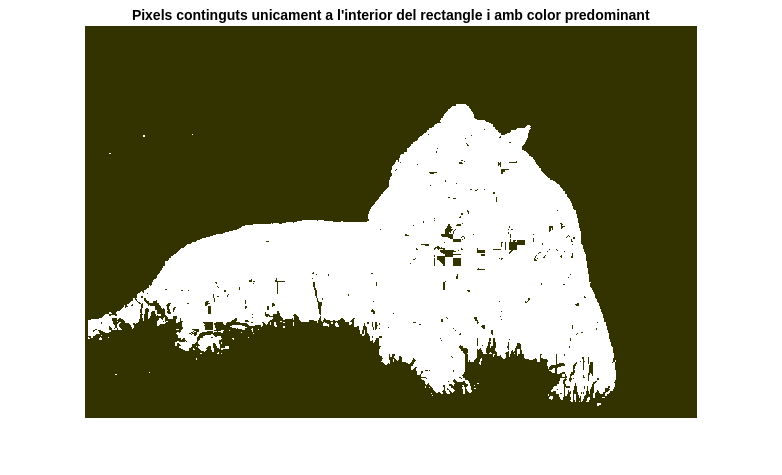

% Decidir per a cada píxel de la matriu H si forma part de la figura o no utilitzant la info de RES, guardar el resultat en vector M i el mostrem per pantalla.

mida_H = size(H,1);

M = zeros(mida_H,1);

for grup_color = 1:mida_H
    
    % primer mirar que estigui al interior rectangle
    if H(grup_color,2) == 1
        if ismember(H(grup_color,1), RES)
            M(grup_color) = 1;
        end
    end 
end


eti = reshape(M, size(I, 1), size(I, 2));

figure, imshow(eti, []);
title("Pixels continguts unicament a l'interior del rectangle i amb color predominant")
colormap colorcube 

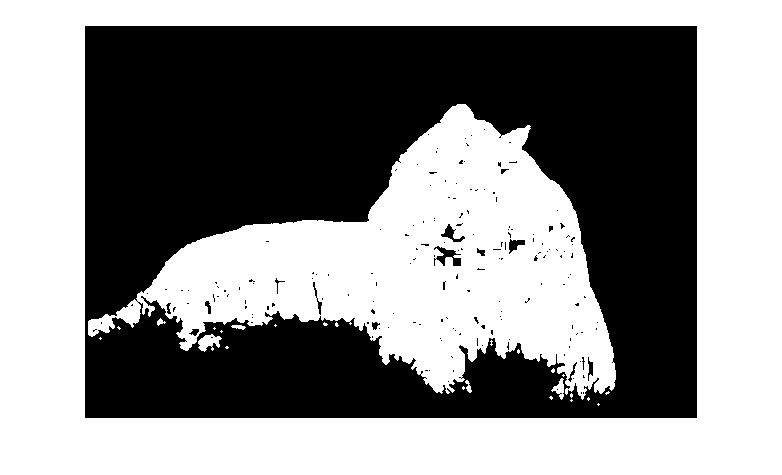

% filtrar el resultat
% ho fare amb operacions morfologiques de open per eliminar soroll blanc

SE = strel('disk',1);
Iopen = imopen(eti,SE);

imshow(Iopen);

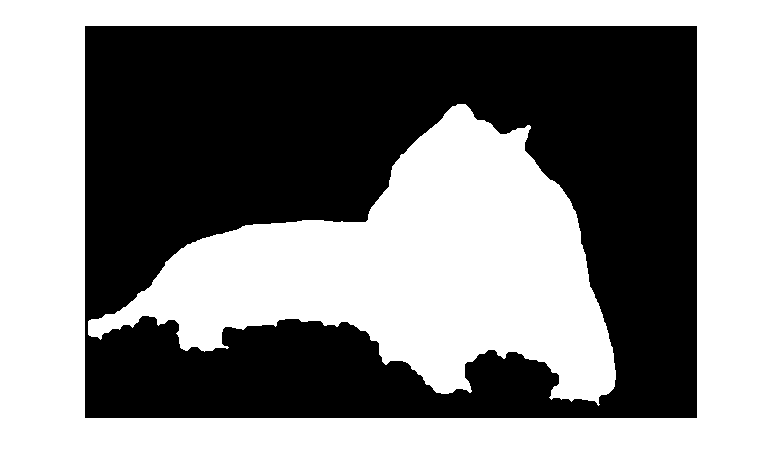

% Fer conex, dilatar primer i despres erode perque torni a la mateixa mida
SE = strel('disk',6); 
Iopen = imclose(Iopen,SE);

imshow(Iopen);

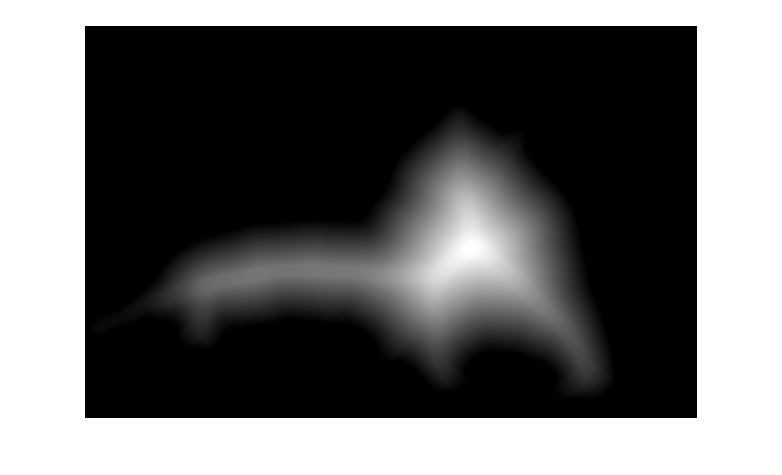

% fer tranformada de la distancia
TD = bwdist(not(Iopen));

% filtre de medianes (aixi eliminem maxims locals propers)  (ajuda a que no talli celules per la meitat)
TDfilt = medfilt2(TD, [20 20]);  

imshow(TDfilt, []);

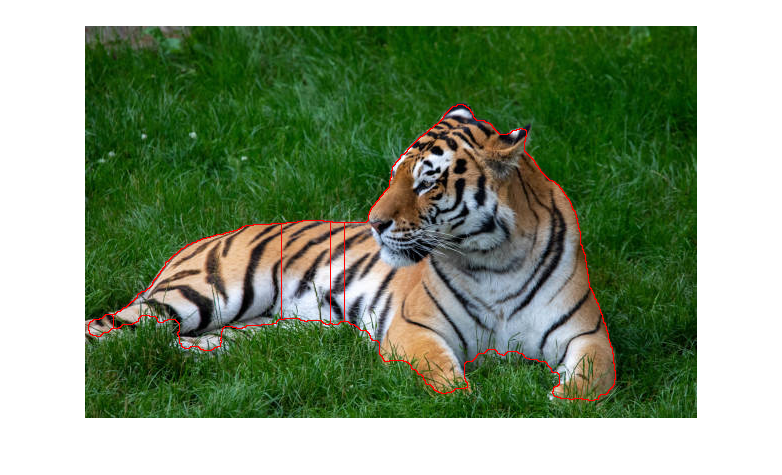


TDfilt = -TDfilt;

% posar el background a menys infinit
TDfilt(Iopen == 0) = -Inf;

WS = watershed(TDfilt);    % on es troba amb altres aigues, li posa etiqueta 0

OL = imoverlay(I, WS==0,'red');   % en vermell les fronteres

imshow(OL,[]);